# Advective Tracer Transport in Porous media

clear, close all, clc
set_demo_defaults();

## Flow problem

Consider the flow of groundwater through a heterogeneous porous medium, given by

$-\nabla\cdot\left[K(\mathbf{x})\nabla h\right] = 0$ on $x \in\left[0,\, 2]\times y \in\left[0,\, 1]$ 

with a unit head gradient from left to right

$h(x=1,y) = 1$ and $h(x=2,y) = 0$.

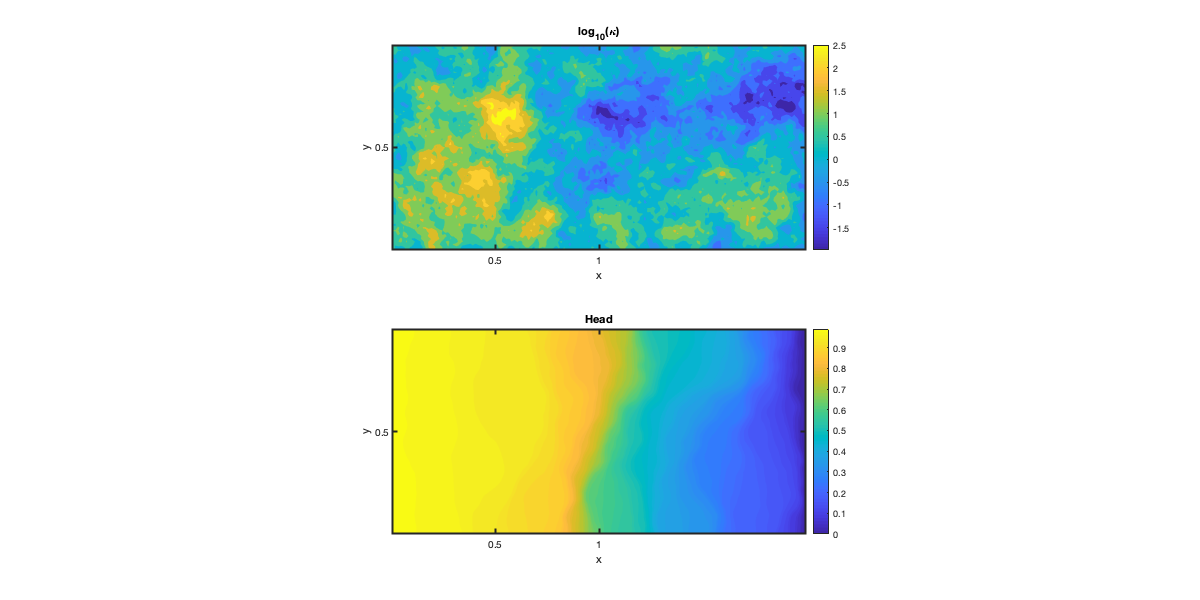

% Grid and discrete operators
Grid.xmin = 0; Grid.xmax = 2; Grid.Nx = 150;
Grid.ymin = 0; Grid.ymax = 1; Grid.Ny = 75;  % The only line that changes
Grid.geom = 'cartesian';
Grid = build_grid(Grid);
[D,G,C,I,M] = build_ops(Grid);


% Permeability field
s = 25061977;
corr_length = 1.;
amplitude = 1;
Kmean = 0;
[Klog,Xc,Yc] = GeneratePermField(Grid,corr_length,amplitude,Kmean,'exp',s);
K = 10.^(Klog);
Kd = comp_mean(K(:),M,-1,Grid,1);

% Linear operator
L_h = -D*Kd*G; fs_h = spalloc(Grid.N,1,0);

% Define the boundary conditions
BC.h.dof_dir   = [Grid.dof_xmin;Grid.dof_xmax];
BC.h.dof_f_dir = [Grid.dof_f_xmin;Grid.dof_f_xmax];
BC.h.g         = [ones(Grid.Ny,1);zeros(Grid.Ny,1)];
BC.h.dof_neu   = [];
BC.h.dof_f_neu = [];
BC.h.qb        = [];
[B_h,N_h,fn_h] = build_bnd(BC.h,Grid,I);

% Solve for temperature
h = solve_lbvp(L_h,fs_h+fn_h,B_h,BC.h.g,N_h);

% Plotting
figure('position',[10 10 1200 600])
subplot 211
[C,h2] = contourf(Xc,Yc,Klog); colorbar
set(h2,'LineColor','none')
set(gca,'xtick',[0 .5 1],'ytick',[0 .5 1])
xlabel 'x', ylabel 'y', title 'log_{10}(\kappa)'
axis equal

subplot 212
[C,h3] = contourf(Xc,Yc,reshape(h,Grid.Ny,Grid.Nx),100); colorbar
set(h3,'LineColor','none')
set(gca,'xtick',[0 .5 1],'ytick',[0 .5 1])
xlabel 'x', ylabel 'y', title 'T'
axis equal
xlabel 'x', ylabel 'y', title 'Head'

## Transport problem

Consider the transort of a conservative tracer given by

(note we should really include porosity here)

$\frac{\partial c}{\partial t}+\nabla\cdot\left[\mathbf{q}c\right] = 0$ on $x \in\left[0,\, 2]\times y \in\left[0,\, 1]$ 

The concentration is initially zero and unit concetration is introduced on the left boundary

tmax = .5;
% Nt = 100;
% dt = tmax/Nt;
theta = 1;

% Define the boundary conditions
BC.c.dof_dir   = [Grid.dof_xmin];
BC.c.dof_f_dir = [Grid.dof_f_xmin];
BC.c.g         = [ones(Grid.Ny,1)];
BC.c.dof_neu   = [];
BC.c.dof_f_neu = [];
BC.c.qb        = [];
[B_c,N_c,fn_c] = build_bnd(BC.c,Grid,I);

% Fluxes and advection matrix
flux = @(u) -Kd*G*u;
res = @(u,cell) L_h(cell,:)*u - fs_h(cell);
q = comp_flux_gen(flux,res,h,Grid,BC.h);
qx = q(1:Grid.Nfx);         qx_max = max(qx);
qy = q(Grid.Nfx+1:Grid.Nf); qy_max = max(qy);
[Qx_c,Qy_c] = comp_cell_center_velocity(q,Xc,Yc,Grid);
Speed = sqrt(Qx_c.^2+Qy_c.^2);
dtx = Grid.dx/qx_max; dty = Grid.dy/qy_max;
dt = min([dtx,dty])/2;
Nt = ceil(tmax/dt)

Nt = 627

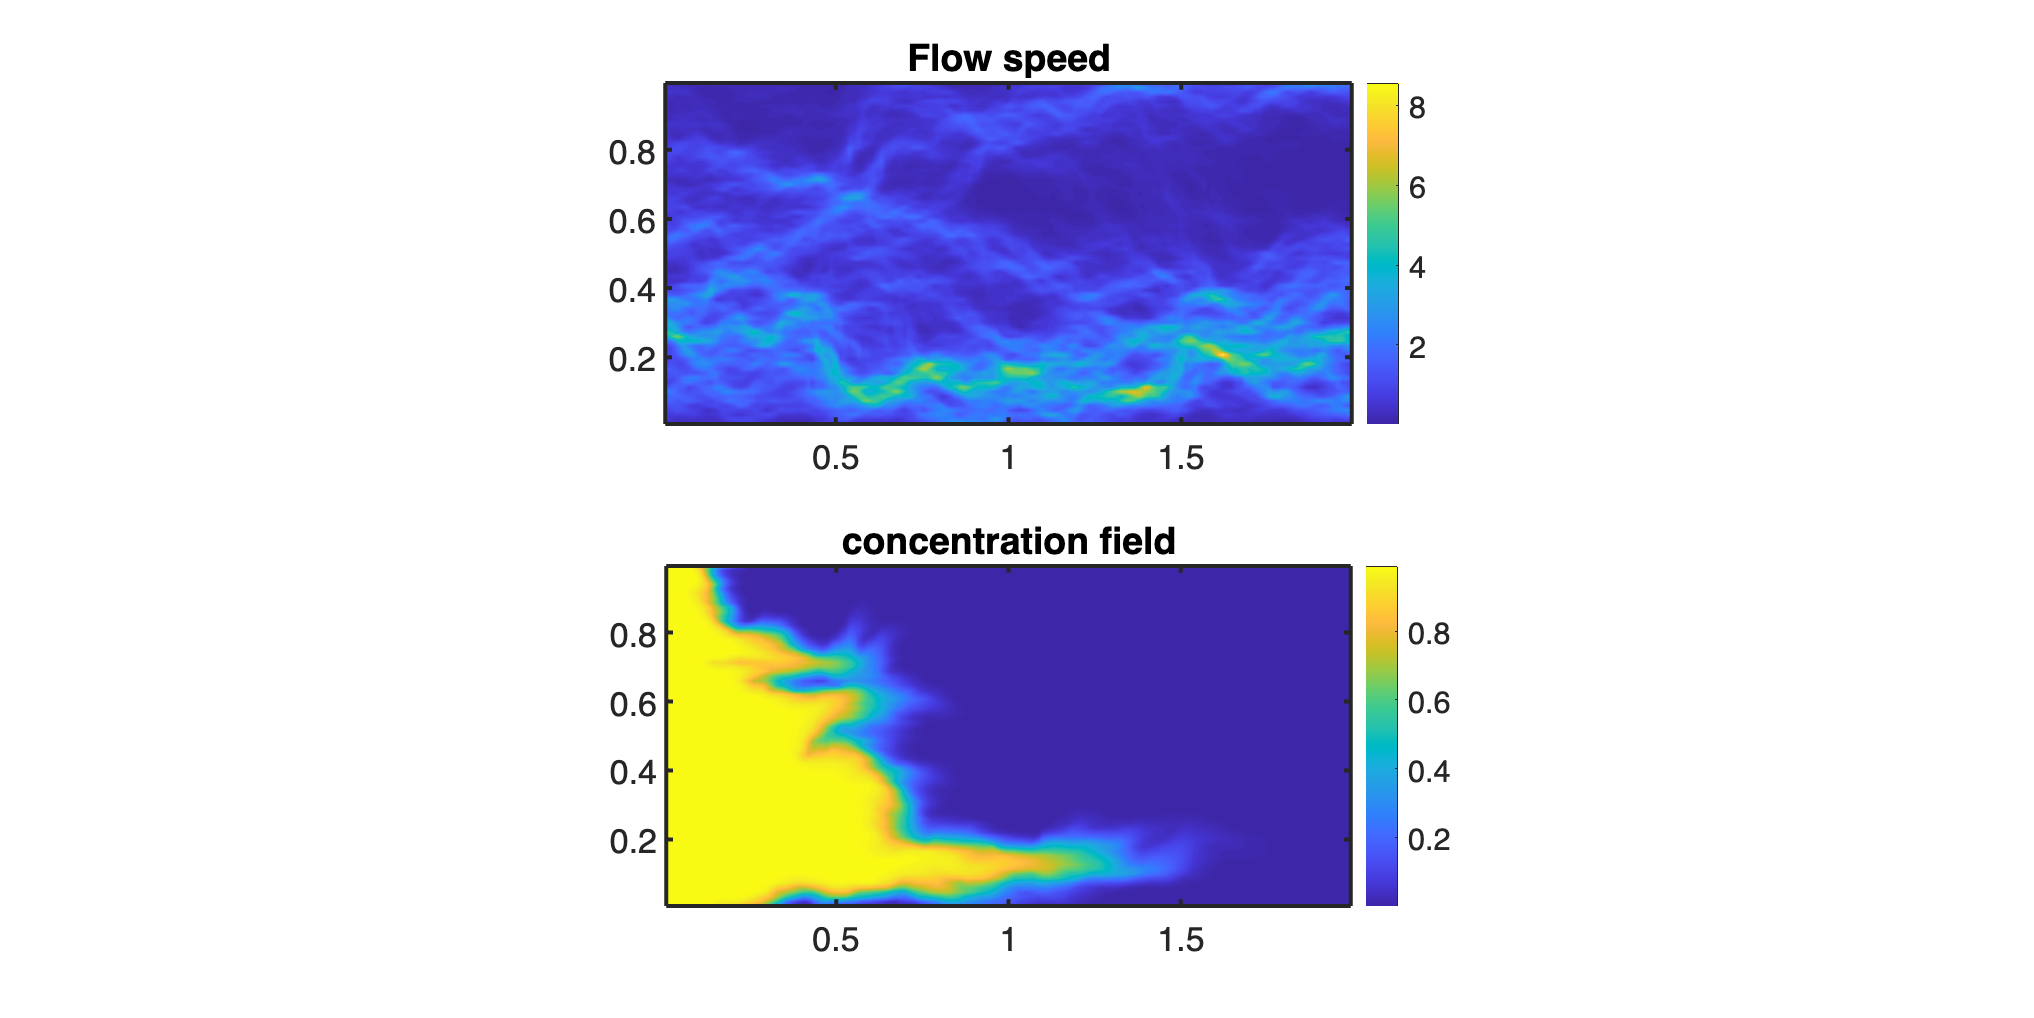

% Linear operators
A = flux_upwind(q,Grid);
L_c = D*A; 
IM = @(dt) I + dt*(1-theta)*L_c;
EX = @(dt) I - dt*theta*L_c;
fs_c = spalloc(Grid.N,1,0);

% Initial condition
c = zeros(Grid.N,1);

figure('position',[10 10 1200 600])
subplot 211
contourf(Xc,Yc,Speed,100,'LineColor','none'), colorbar
title 'Flow speed'
axis equal
% Time evolution
for i = 1:Nt
    c = solve_lbvp(IM(dt),EX(dt)*c+dt*fs_c+fn_c,B_c,BC.c.g,N_c);
end
subplot 212
contourf(Xc,Yc,reshape(c,Grid.Ny,Grid.Nx),100,'LineColor','none'), colorbar
title 'concentration field'
axis equal

## Auxillary functions

The function below generates a correlated random field.

function [K,X,Y] = GeneratePermField(Grid,corr_length,amp,Kmean,type,rng_state)
[X,Y] = meshgrid(Grid.xc,Grid.yc);
x = X(:); y = Y(:);
if strcmp(type,'exp')
    sig = -log(.1)/corr_length;
else
    error('Unknown covariance model')
end
Cov = zeros(Grid.N,Grid.N);
for i = 1:Grid.N
    dist = sqrt((x(i) - x).^2 + (y(i) - y).^2);
    if strcmp(type,'exp')
        Cov(i,:) = exp(-sig * dist);
    else
        error('Unknown covariance model')
    end
end
rng(rng_state);
% Cholesky factorization is equivalent to square root of a matrix 
% Cov = L*L' <=> L ~ sqrt(Cov)
L = chol(Cov,'lower');
Kpert = reshape(L*randn(Grid.N,1),Grid.Ny,Grid.Nx);
K = Kmean + Kpert;
end

The function below averages the fluxes from the cell faces to the cell centers

function [Vx_c,Vy_c] = comp_cell_center_velocity(v,Xc,Yc,Grid)
% author: Marc Hesse
% date: 29 May 2020
% Description:
% This functions averages the face velocities to the cell centers for a
% standard tensor-product staggered mesh.

% Interploate x-velocities
Vx = reshape(v(1:Grid.Nfx),Grid.Ny,Grid.Nx+1);
[Xx,Yx] = meshgrid(Grid.xf,Grid.yc);
Vx_c = interp2(Xx,Yx,Vx,Xc,Yc);

% Interpolate y-velocities
Vy = reshape(v(Grid.Nfx+1:end),Grid.Ny+1,Grid.Nx);
[Xy,Yy] = meshgrid(Grid.xc,Grid.yf);
Vy_c = interp2(Xy,Yy,Vy,Xc,Yc);
end